% Define the data for lower limit, upper limit, and frequency
lowerLimits = [5, 10, 15, 20, 25, 30, 35, 40, 45]; 
upperLimits = [10,15, 20, 25, 30, 35, 40, 45, 50]; 
frequencies = [3,0,1,2,11,3,10,15,5];  

% Create a table in MATLAB
dataTable = table(lowerLimits', upperLimits', frequencies',...
    'VariableNames', {'LowerLimit', 'UpperLimit', 'Frequency'});

% Display the table
disp(dataTable);

    LowerLimit    UpperLimit    Frequency
    __________    __________    _________

         5            10            3    
        10            15            0    
        15            20            1    
        20            25            2    
        25            30           11    
        30            35            3    
        35            40           10    
        40            45           15    
        45            50            5    




% Calculate mean, median, mode, and standard deviation
data = [];
for i = 1:length(lowerLimits)
    data = [data, ones(1, frequencies(i)) * ((upperLimits(i) + lowerLimits(i)) / 2)];
end

meanValue = mean(data);
medianValue = median(data);
modeValue = mode(data);
stdDeviation = std(data);

% Calculate empirical_mode, mode_shift, and Karl
empirical_mode = 3 * medianValue - 2 * meanValue;
mode_shift = modeValue - empirical_mode;
Karl = (meanValue - modeValue) / stdDeviation;

% Display the calculated statistics
fprintf('Mean: %.2f\n', meanValue);

Mean: 34.70


fprintf('Median: %.2f\n', medianValue);

Median: 37.50


fprintf('Mode: %.2f\n', modeValue);

Mode: 42.50


fprintf('Standard Deviation: %.2f\n', stdDeviation);

Standard Deviation: 10.31


fprintf('Empirical Mode: %.2f\n', empirical_mode);

Empirical Mode: 43.10


fprintf('Mode Shift: %.2f\n', mode_shift);

Mode Shift: -0.60


fprintf('Karl: %.2f\n', Karl);

Karl: -0.76


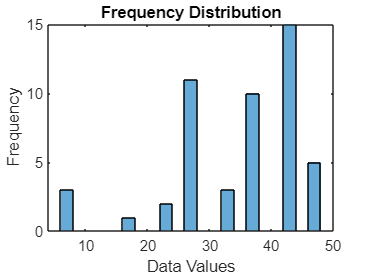


% Plotting the line graph
figure;
histogram(data, 'BinWidth', 2); % Change the 'BinWidth' according to your preference
title('Frequency Distribution');
xlabel('Data Values');
ylabel('Frequency');